# **影像邊緣檢測實驗 - 基本原理與實作**

**作者: 呂聖韡**

**日期: 2024/10/31**

**目的: 理解基本的邊緣檢測原理**

## **1.創建基本測試影像**

首先創建一個包含方形和圓形的測試影像

這個步驟展示如何從基本幾何形狀構建測試影像

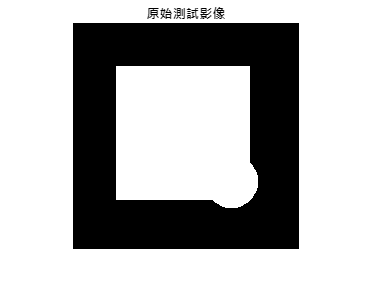

% 創建空白畫布
testImage = zeros(256, 256);

% 添加方形
testImage(50:200, 50:200) = 1;

% 添加圓形
[X, Y] = meshgrid(1:256, 1:256);
circle = sqrt((X-180).^2 + (Y-180).^2) <= 30;
testImage = testImage + circle;
testImage = min(testImage, 1);

% 顯示原始測試影像
figure
imshow(testImage)
title('原始測試影像')

## **2.添加噪聲**

為了模擬真實情況，我添加高斯噪聲

這步驟展示如何處理帶有噪聲的影像

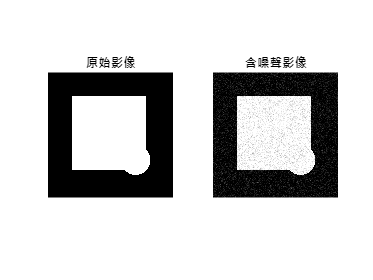

% 生成並添加隨機噪聲
rng(42);
noise = randn(256) * 0.1;
noisyImage = testImage + noise;
noisyImage = max(0, min(1, noisyImage));

% 顯示添加噪聲後的影像
figure
subplot(1,2,1), imshow(testImage), title('原始影像')
subplot(1,2,2), imshow(noisyImage), title('含噪聲影像')

## **3.計算圖像梯度**

邊緣檢測的核心是計算圖像梯度

分別計算水平和垂直方向的梯度

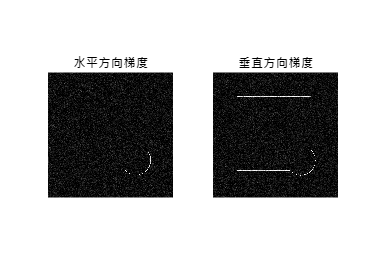

% 計算水平梯度
Gx = zeros(size(noisyImage));
Gx(:,2:end) = diff(noisyImage, 1, 2);

% 計算垂直梯度
Gy = zeros(size(noisyImage));
Gy(2:end,:) = diff(noisyImage, 1, 1);

% 顯示梯度結果
figure
subplot(1,2,1), imshow(abs(Gx)), title('水平方向梯度')
subplot(1,2,2), imshow(abs(Gy)), title('垂直方向梯度')

## **4.計算梯度幅值**

使用畢氏定理計算總梯度幅值

這個步驟將水平和垂直梯度合成為單一的邊緣強度圖

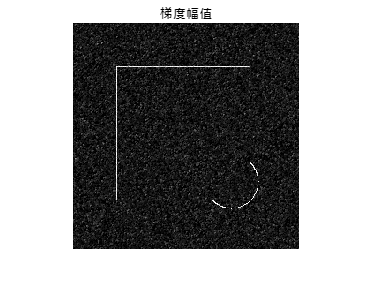

gradientMagnitude = sqrt(Gx.^2 + Gy.^2);

figure
imshow(gradientMagnitude)
title('梯度幅值')

## **5. 不同閾值的邊緣檢測結果**

比較不同閾值對邊緣檢測結果的影響

這個步驟展示閾值選擇的重要性

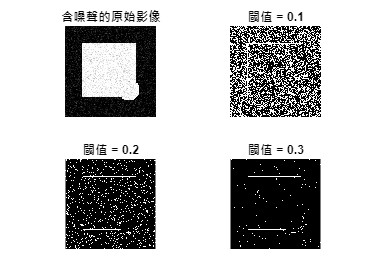

thresholds = [0.1, 0.2, 0.3];
figure
subplot(2,2,1), imshow(noisyImage), title('含噪聲的原始影像')

for i = 1:length(thresholds)
    edges = gradientMagnitude > thresholds(i);
    subplot(2,2,i+1)
    imshow(edges)
    title(['閾值 = ' num2str(thresholds(i))])
end

## **6. 定量分析**

計算並比較不同閾值下檢測到的邊緣像素數量

edgeCounts = zeros(size(thresholds));
for i = 1:length(thresholds)
    edges = gradientMagnitude > thresholds(i);
    edgeCounts(i) = sum(edges(:));
end

% 創建並顯示結果表格
T = table(thresholds', edgeCounts', ...
    'VariableNames', {'閾值', '邊緣像素數量'});
disp('不同閾值的邊緣檢測結果統計：')

不同閾值的邊緣檢測結果統計：


disp(T)

    閾值    邊緣像素數量
    ____    __________

    0.1       26243   
    0.2        6147   
    0.3        1419   



## **7.結果討論**

** 閾值 0.1:**

檢測到最多的邊緣

但也包含較多噪聲

**閾值 0.2:**

提供較好的平衡

主要邊緣清晰可見

**閾值 0.3:**

噪聲影響最小

但可能遺漏部分邊緣